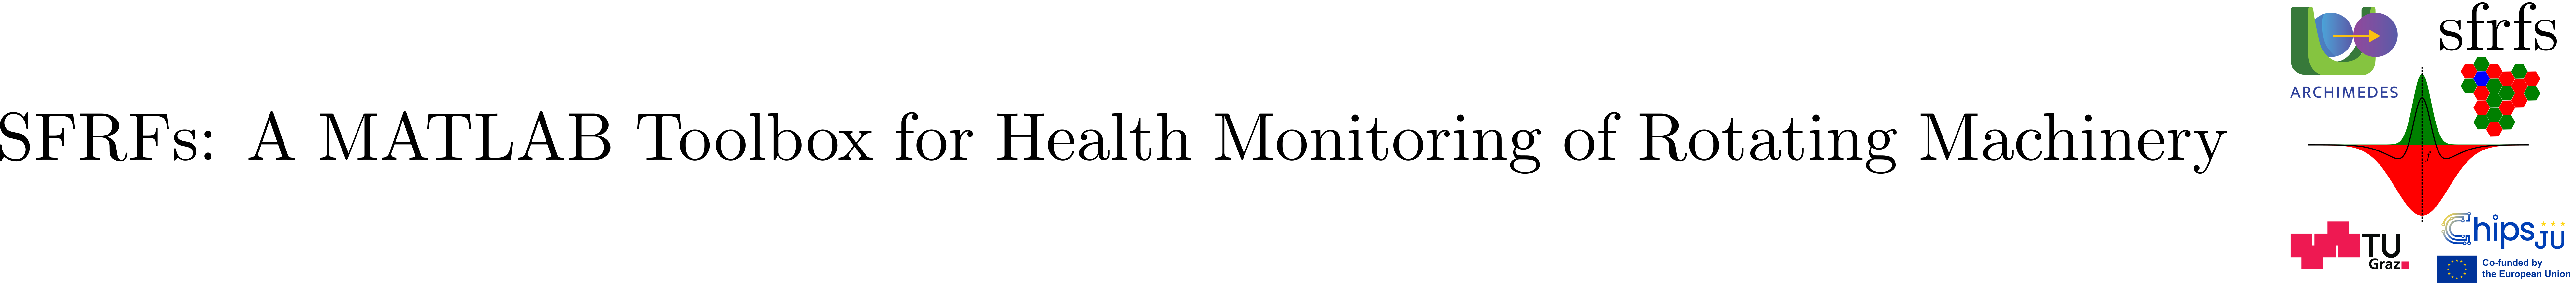

# SFRFsLogger

## Summary

`SFRFsLogger` provides a per-process singleton logging service for the SFRFs framework, backed by `java.util.logging`. It automatically creates one log file per MATLAB process or parallel worker and supports configurable levels, file rotation, formatting, and optional debug metadata injection.

**Key features**

- Per-process and per-worker singleton logger

- Automatic file separation by worker ID

- Configurable pattern, rotation, level, and formatter via properties

- Supports standard logging levels (INFO, WARNING, SEVERE, etc.)

- Optional debug mode with caller and line metadata

- Compatible with parallel execution environments

## Description

`SFRFsLogger` is a lightweight, per-process singleton logger designed for the SFRFs framework. It wraps MATLAB’s Java logging interface, creating an isolated logger instance for each MATLAB session or parallel worker. Each instance writes to a dedicated log file identified by its worker ID, ensuring safe and traceable logging in both serial and parallel execution contexts.

The logger is configured via a `logging.properties` file and supports file rotation, customizable output formatting, and standard severity levels. An optional debug mode enriches log entries with caller, file, and line information, supporting transparent traceability during development and troubleshooting.

The class centralizes all logging behavior for the toolbox and can be accessed anywhere via `SFRFsLogger.getLogger()`, ensuring consistent and reproducible logging across all components.

### Public properties

### Public methods

### Logging configuration

The logger is configured via a `logging.properties` file shipped with the toolbox.

Log files are written to:

- `fullfile(prefdir,'sfrfs'``,``'logs'``)`

and are named:

- `SFRFsLogger_worker<ID>.log`

**Important:** The logging configuration cannot be modified after MATLAB has started.

To customize the log message format, set the JVM system property **before launching MATLAB**, for example:

- `export _JAVA_OPTIONS = '-Djava.util.logging.SimpleFormatter.format="%1$tF %1$tT %4$s %3$s %5$s%6$s%n"'`

## `Example`

### `Obtaining logger instance`

% Obtain the per-process singleton logger
logger = SFRFsLogger.getLogger()

logger =   SFRFsLogger with properties:

                 logFolder: '/home/stan/.matlab/R2025b/sfrfs/logs'
                   pattern: 'SFRFsLogger_worker%u.log'
                     limit: '1000000'
                     count: '100'
                    append: 'true'
                     level: 'FINE'
                 formatter: 'java.util.logging.SimpleFormatter'
          LOGGER_BASE_NAME: 'SFRFsLogger'
      FILE_HANDLER_PATTERN: 'SFRFsLogger.FileHandler.pattern'
        FILE_HANDLER_LIMIT: 'SFRFsLogger.FileHandler.limit'
        FILE_HANDLER_COUNT: 'SFRFsLogger.FileHandler.count'
       FILE_HANDLER_APPEND: 'SFRFsLogger.FileHandler.append'
        FILE_HANDLER_LEVEL: 'SFRFsLogger.FileHandler.level'
    FILE_HANDLER_FORMATTER: 'SFRFsLogger.FileHandler.formatter'
                LOG_FOLDER: 'SFRFsLogger.logFolder'


### Logging messages

% Standard log levels
logger.info('Starting SFRFs processing...');
logger.warning('Low signal-to-noise ratio detected');
logger.severe('Unable to load snapshot parameters');

% Fine-grained debugging (if enabled in logging.properties)
logger.fine('Entering compute loop');
logger.finer('Intermediate values available');
logger.finest('Full internal state dump');

% Enable call-site metadata (file, line, method)
logger.enableDebug();

logger.info('This message will include caller context');

% Disable again if not needed
logger.disableDebug();

### Inspecting log files

To see the logged messages 

% we inspect the main thread log file
workerID = 0;
nLines = 7;
showlog(workerID,nLines)


Showing last 7 line(s) of:
/home/stan/.matlab/R2025b/sfrfs/logs/SFRFsLogger_worker0.log.0

2025-12-09 15:23:48 FINE SFRFsLogger_worker0 Entering compute loop
2025-12-09 15:23:55 INFO SFRFsLogger_worker0 [LiveEditorEvaluationHelperEeditor4CAC3226motw@SFRFsLogger.m:352] Starting SFRFs processing...
2025-12-09 15:23:55 WARNING SFRFsLogger_worker0 [LiveEditorEvaluationHelperEeditor4CAC3226motw@SFRFsLogger.m:357] Low signal-to-noise ratio detected
2025-12-09 15:23:55 SEVERE SFRFsLogger_worker0 [LiveEditorEvaluationHelperEeditor4CAC3226motw@SFRFsLogger.m:362] Unable to load snapshot parameters
2025-12-09 15:23:55 FINE SFRFsLogger_worker0 [LiveEditorEvaluationHelperEeditor4CAC3226motw@SFRFsLogger.m:367] Entering compute loop
2025-12-09 15:23:55 INFO SFRFsLogger_worker0 [LiveEditorEvaluationHelperEeditor4CAC3226motw@SFRFsLogger.m:352] This message will include caller context



## API documentation

### MATLAB help

help SFRFsLogger

  SFRFsLogger - Singleton logger supporting parallel workers
 
  Provides a per-process singleton logger instance writing to unique files
  named by worker ID (0 for main MATLAB, >0 for parallel workers).
  Supports all standard java.util.logging levels.
 
  Usage:
    logger = SFRFsLogger.getLogger();
    logger.info('A relevant bit of information');
    logger.warning('A warning message');
    logger.severe('A message signaling a severe condition');
    logger.finer('An informative message for debugging');
    logger.finest('A very detailed message');
    logger.config('A relevant remark on configuration');
 
  Log files:
    Files named 'SFRFsLogger_worker<ID>.log' saved in the configured log 
    folder.

    Documentation for SFRFsLogger
       doc SFRFsLogger




### MATLAB documentation

doc SFRFsLogger

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

The source of this class can be found in [SFRFsLogger](matlab:open('../../SFRFsLogger.m')).

## Auxiliary functions

### Show log file content

function showlog(workerID, nLines)
% SHOWLOG Display the last N lines of the most recent SFRFs log file
%
%   showlog()             % main worker, last 10 lines
%   showlog(0)            % main worker, last 10 lines
%   showlog(0, 25)        % main worker, last 25 lines
%   showlog(3, 100)       % worker 3, last 100 lines

    arguments
        workerID (1,1) double ...
            {mustBeNonnegative, mustBeInteger} = 0
        nLines   (1,1) double ...
            {mustBePositive, mustBeInteger}    = 10
    end

    logger = SFRFsLogger.getLogger();

    % Pattern: SFRFsLogger_worker<ID>.log.<n>
    pattern = sprintf('SFRFsLogger_worker%d.log.*', workerID);
    files = dir(fullfile(logger.logFolder, pattern));

    % Remove lock files
    isLocked = endsWith({files.name}, ".lck");
    files = files(~isLocked);

    if isempty(files)
        warning('No log files found for worker %d in %s', ...
            workerID, logger.logFolder);
        return
    end

    % Pick most recent file
    [~, idx] = max([files.datenum]);
    logFile = fullfile(files(idx).folder, files(idx).name);

    % Read file
    txt = readlines(logFile);
    n = numel(txt);

    if n == 0
        fprintf('Log file is empty: %s\n', logFile);
        return
    end

    % Safe start index (won't break if less lines exist)
    startIdx = max(1, n - nLines + 1);
    tail = txt(startIdx:end);

    fprintf('\nShowing last %d line(s) of:\n%s\n\n', ...
        numel(tail), logFile);
    fprintf('%s\n', tail);
end

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).